% This script demonstrates the differences between the scaled linear
% control law and the linear control law determined by solving an
% optimization problem on the robot arm benchmark.

% load benchmark parameter
Param = param_robotArm();

## SCALED LINEAR CONTROL LAW

% define algorithm options
Opts = [];

Opts.controller = 'linear';                 % controller 
Opts.approx.method = 'scaled';              % method to approx. contr. law
Opts.Q = diag([10,10,1,1]);                 % state weighting matrix
Opts.R = diag([0;0]);                       % input weighting matrix 
Opts.refTraj.Q = eye(4)./(0.05^2);          % state weighting (ref. traj.)
Opts.refTraj.R = diag([1;1]./([3;1].^2));   % input weighting (ref. traj.)

% controler synthesis
clock = tic;
[objContrScaled,resContrScaled] = ...
    convexInterpolationControl('robotArm',Param,Opts);

Time step: 1
Time step: 2
Time step: 3
Time step: 4
Time step: 5
Time step: 6
Time step: 7
Time step: 8
Time step: 9
Time step: 10


tComp = toc(clock);

disp([newline,'Computation time (scaled linear controller): ', ...
      num2str(tComp),'s', newline]);


Computation time (scaled linear controller): 73.7094s



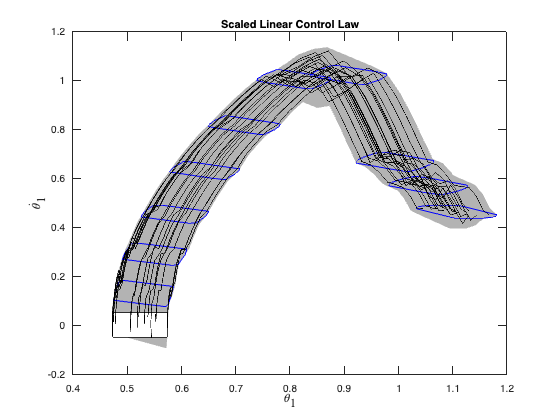


% simulation 
[resSim,~,~] = simulateRandom(objContrScaled);

% visualization
figure; hold on; box on
plotReach(resContrScaled,[1,3],[.7 .7 .7]);
plotReachTimePoint(resContrScaled,[1,3],'b');
plot(Param.R0,[1,3],'FaceColor','w','EdgeColor','k');
plotSimulation(resSim,[1,3],'k');
xlabel('$\theta_1$','interpreter','latex');
ylabel('$\dot\theta_1$','interpreter','latex');
title('Scaled Linear Control Law');

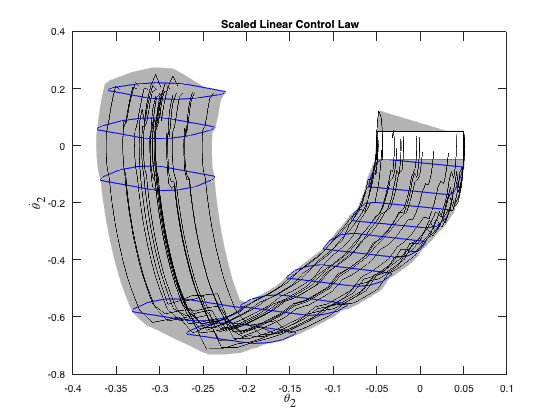


figure; hold on; box on
plotReach(resContrScaled,[2,4],[.7 .7 .7]);
plotReachTimePoint(resContrScaled,[2,4],'b');
plot(Param.R0,[2,4],'FaceColor','w','EdgeColor','k');
plotSimulation(resSim,[2,4],'k');
xlabel('$\theta_2$','interpreter','latex');
ylabel('$\dot\theta_2$','interpreter','latex');
title('Scaled Linear Control Law');

## OPTIMIZED LINEAR CONTROL LAW

% adapt algorithm options
Opts.controller = 'linear';             % controller
Opts.approx.method = 'optimized';       % method to approx. contr. law
Opts.approx.lambda = 0.5;               % tradeoff for approx. contr. law

% controller synthesis
clock = tic;
[objContrOptimized,resContrOptimized] = ...
    convexInterpolationControl('robotArm',Param,Opts);

Time step: 1
Time step: 2
Time step: 3
Time step: 4
Time step: 5
Time step: 6
Time step: 7
Time step: 8
Time step: 9
Time step: 10


tComp = toc(clock);

disp([newline,'Computation time (optimized linear controller): ', ...
      num2str(tComp),'s']);


Computation time (optimized linear controller): 81.9373s


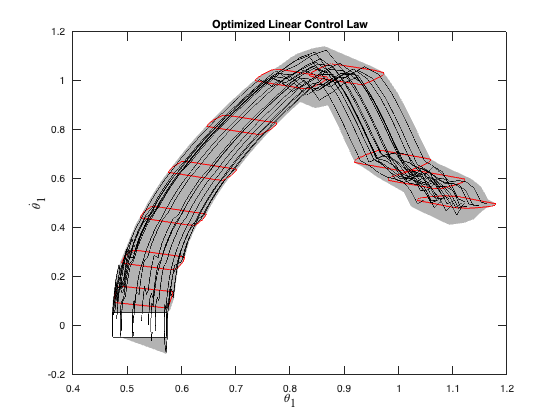


% simulation 
[resSim,~,~] = simulateRandom(objContrOptimized);

% visualization
figure; hold on; box on
plotReach(resContrOptimized,[1,3],[.7 .7 .7]);
plotReachTimePoint(resContrOptimized,[1,3],'r');
plot(Param.R0,[1,3],'FaceColor','w','EdgeColor','k');
plotSimulation(resSim,[1,3],'k');
xlabel('$\theta_1$','interpreter','latex');
ylabel('$\dot\theta_1$','interpreter','latex');
title('Optimized Linear Control Law');

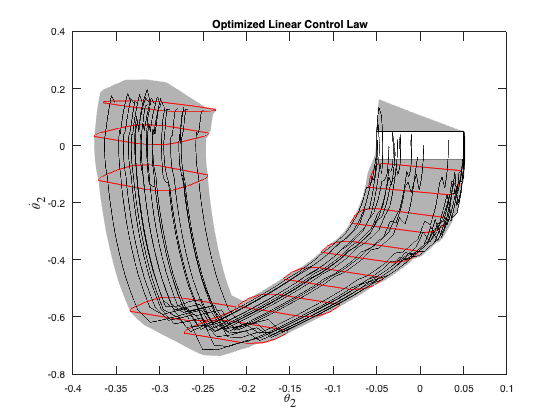


figure; hold on; box on
plotReach(resContrOptimized,[2,4],[.7 .7 .7]);
plotReachTimePoint(resContrOptimized,[2,4],'r');
plot(Param.R0,[2,4],'FaceColor','w','EdgeColor','k');
plotSimulation(resSim,[2,4],'k');
xlabel('$\theta_2$','interpreter','latex');
ylabel('$\dot\theta_2$','interpreter','latex');
title('Optimized Linear Control Law');